1. Загрузите данные **ex8data1.mat **из файла.

2. Постройте график загруженных данных в виде диаграммы рассеяния.

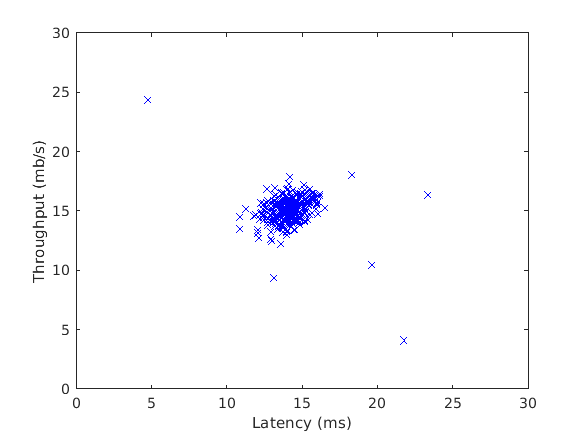

load('ex8data1.mat');

plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

3. Представьте данные в виде двух независимых нормально распределенных случайных величин.

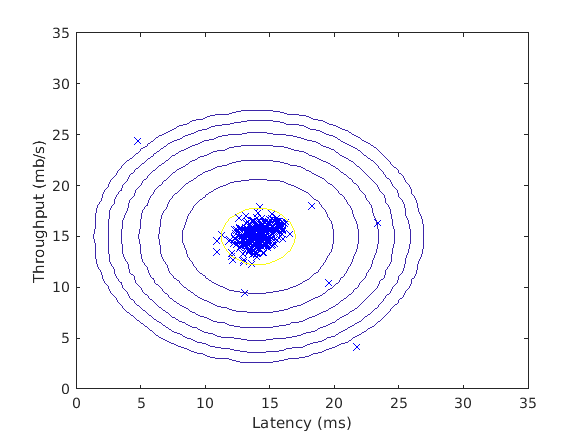

[mu, sigma2] = estimateGaussian(X);

p = multivariateGaussian(X, mu, sigma2);

visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

4. Оцените параметры распределений случайных величин.

5. Постройте график плотности распределения получившейся случайной величины в виде изолиний, совместив его с графиком из пункта 2.

6. Подберите значение порога для обнаружения аномалий на основе валидационной выборки. В качестве метрики используйте F1-меру.

7. Выделите аномальные наблюдения на графике из пункта 5 с учетом выбранного порогового значения.

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 8.990853e-05


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.875000


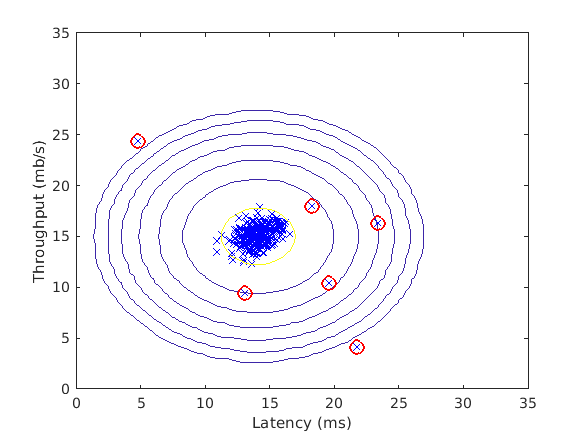

outliers = find(p < epsilon);

visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

8. Загрузите данные **ex8data2.mat **из файла.

9. Представьте данные в виде 11-мерной нормально распределенной случайной величины.

10. Оцените параметры распределения случайной величины.

11. Подберите значение порога для обнаружения аномалий на основе валидационной выборки. В качестве метрики используйте F1-меру.

12. Выделите аномальные наблюдения в обучающей выборке. Сколько их было обнаружено? Какой был подобран порог?

load('ex8data2.mat');

[mu, sigma2] = estimateGaussian(X);

p = multivariateGaussian(X, mu, sigma2);

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 1.377229e-18


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.615385


fprintf('# Outliers found: %d\n', sum(p < epsilon));

# Outliers found: 117
